**Даны числа c_k— коэффициенты разложения некоторой элементарной функции x=x(t) в ряд Фурье по указанной системе многочленов. Восстановить функцию x:**

- **построить график частичной суммы ряда Фурье достаточно высокого порядка;**

- **по виду графика сделать предположение о том, какова формула функции x. **

Инициализируем переменные

syms t
n = 100;
c_k = zeros(1, n+1);

Задаём коэффициенты c_k

c_k(1) = -sqrt(pi)*log(2);           
for k = 1:n
    c_k(k+1) = (-1)^(k-1)*sqrt(2*pi)/k;
end

Строим сетку tt и вычисляем T_k(tt)

tt = linspace(-1,1,1001);         % сетка для графика
M  = numel(tt);
Tmat       = zeros(n+1,M);
Tmat(1,:)  = 1;                   % T_0
if n>=1, Tmat(2,:) = tt; end      % T_1
for m = 2:n
    Tmat(m+1,:) = 2*tt.*Tmat(m,:) - Tmat(m-1,:);
end

Считаем частичную сумму Cheb_n(tt)

Cheb_val = zeros(1,M);
for m = 0:n
    ck = c_k(m+1);
    if ck==0, continue, end
    Tk = Tmat(m+1,:);
    phi = (m==0)*( Tk /sqrt(pi)) + ...
          (m> 0)*(sqrt(2/pi)*Tk);
    Cheb_val = Cheb_val + ck*phi;
end

Строим график

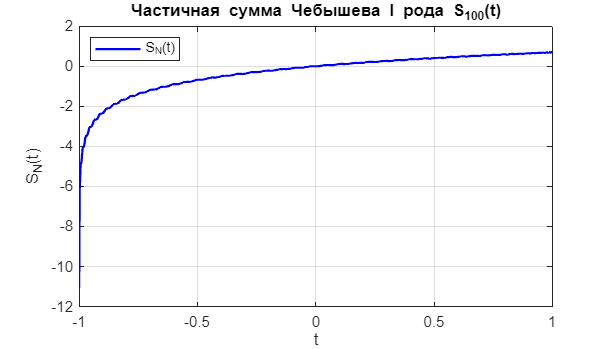

figure('Position',[200 200 700 400]);
plot(tt,Cheb_val,'b','LineWidth',1.5); hold on
xlabel('t'); ylabel('S_N(t)');
title(sprintf('Частичная сумма Чебышева I рода S_{%d}(t)',n));
legend('S_N(t)','Location','northwest');
grid on

Предположу, что x(t)=ln(t+1)

Рассчитаем нормы и несколько первых коэффицентов Фурье

Tk_f = @(m,t) chebyshevT(m,t);    
ves    = @(t) 1./sqrt(1-t.^2);      
f     = @(t) (log((1+t)));              

m_max  = 7;                          
c_log = zeros(1,m_max+1);
for m = 0:m_max
    integrand  = @(t) f(t).*Tk_f(m,t).*ves(t);
    I          = integral(integrand,-1,1,'ArrayValued',true);
    scale      = (m==0)*(1/sqrt(pi)) + (m>0)*sqrt(2/pi);
    c_log(m+1) = scale * I;
end
norm_c = norm(c_k);                     
f_sq        = @(t) f(t).^2 .* ves(t);
norm_func   = sqrt(integral(f_sq,-1,1,'ArrayValued',true));

fprintf('\nL2-норма (частичная сумма):  %.6f\n', norm_c);


L2-норма (частичная сумма):  3.432535


fprintf('L2-норма функции ln(t+1): %.6f\n\n', norm_func);

L2-норма функции ln(t+1): 3.439202



fprintf(' k |   c_k    |   c_k(ln(t+1)\n');

 k |   c_k    |   c_k(ln(t+1)


fprintf('---+-----------------+-----------------\n');

---+-----------------+-----------------


for m = 0:m_max
    fprintf('%2d | %15.6f | %15.6f\n', ...
            m, c_k(m+1), c_log(m+1));
end

 0 |       -1.228571 |       -1.228571
 1 |        2.506628 |        2.506628
 2 |       -1.253314 |       -1.253314
 3 |        0.835543 |        0.835543
 4 |       -0.626657 |       -0.626657
 5 |        0.501326 |        0.501326
 6 |       -0.417771 |       -0.417771
 7 |        0.358090 |        0.358090


Нормы и коэффиценты разложения максимально близки=> гипотеза правдоподобна